# Module 5: Chromatic aberration correction

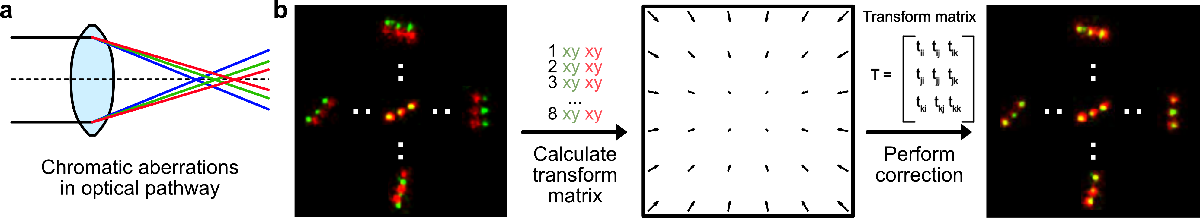

Often, chromatic aberrations are present in the optical pathway of the microscope. This entails that fluorophores with different emission wavelengths are positions slightly differently on the final image. Chromatic aberration correction is the process of defining this chromatic aberration and correcting for it.

## Variable initialisation

% First we load the images and view the chromatic abberration
greenim = double(imread('Data\ChromAbb_Green.png'));
redim = double(imread('Data\ChromAbb_Red.png'));

%And we create an RGB image so both channels can be seen
imRGB = zeros(size(greenim,1),size(greenim,2),3);
%Note that the third dimension in an RGB image is [red, green, blue]
%channels
imRGB(:,:,1) = redim./max(max(redim));
imRGB(:,:,2) = greenim./max(max(greenim));

## Visualisation of chromatic aberration

As chromatic aberration is normally on the order of ~100 nm over a field-of-view of 100s of micrometer, visualising simply the complete field-of-view does not adequately show the chromatic aberrations. Therefore, we plot a 'clover', where we take small subregions of the very top, bottom, middle, left, and right of the field-of view.

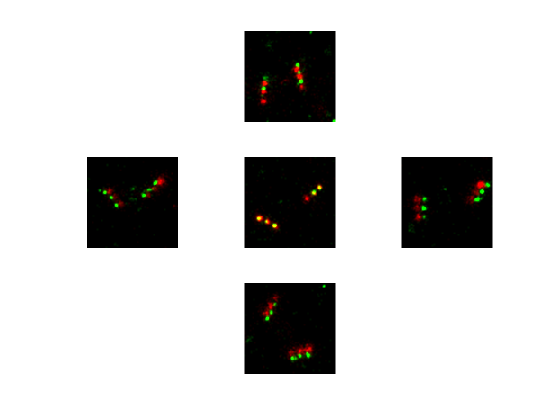

%We also plot a few sections of the image so we can view detailed parts
subplotsize = 100;
figure()
subplot(3,3,2)
imshow(imRGB(170:170+subplotsize,3970:3970+subplotsize,:));
subplot(3,3,4)
imshow(imRGB(4040:4040+subplotsize,1300:1300+subplotsize,:));
subplot(3,3,5)
imshow(imRGB(3750:3750+subplotsize,4140:4140+subplotsize,:));
subplot(3,3,6)
imshow(imRGB(3450:3450+subplotsize,7390:7390+subplotsize,:));
subplot(3,3,8)
imshow(imRGB(6680:6680+subplotsize,4150:4150+subplotsize,:));

## Calculation of chromatic aberration

The chromatic aberration is calculted by comparing points in the datasets of different emission colours. These points are hand-picked between the two datasets.

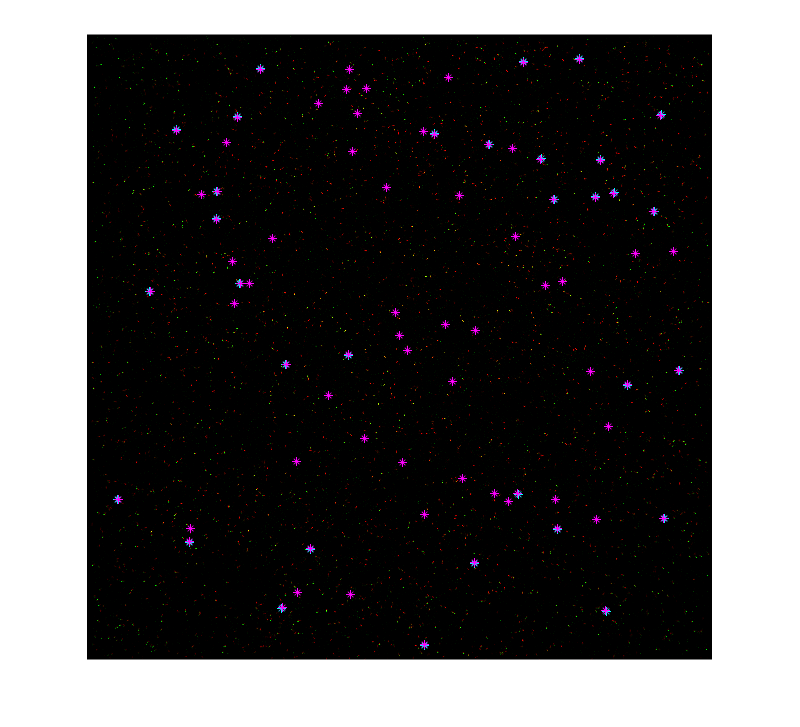

%Load the points - they are stored as greenpts and redpts
load('Data/ChromAbb_points.mat')
%We can view the full image with the points overlaid and investigate them
%if wanted
figure()
imshow(imRGB)
hold on
%Green points will be shown in cyan
scatter(greenpts(:,1),greenpts(:,2),'c*')
%Red points will be shown in magenta
scatter(redpts(:,1),redpts(:,2),'m*')

%You are encouraged to open the image in a figure window (arrow on
%top-right of image), and view specific hand-picked points

Now a transformation can be calculated that maps the chromatic abberation - an affine transformation will be good for this.

%We use the fitgeotrans function
chromAbbTransform = fitgeotrans(redpts,greenpts,'affine');

And we can use this transform variable to create a chromatic-abberation-corrected red image:

%We use the imwarp function, with additional the 'OutputView' setting, to
%ensure that the corrected red image has the same size as the original
%images
redimCorrected = imwarp(redim,chromAbbTransform,'OutputView',imref2d(size(greenim)));

## Visualisation of corrected chromatic aberration

Now we can repeat the visualisation of the sections to view the effect of the correction

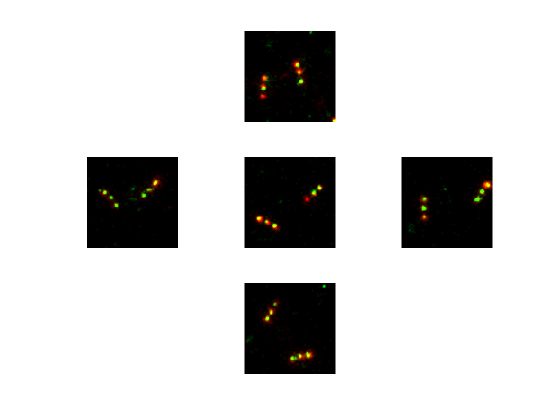

imRGBcorrected = zeros(size(greenim,1),size(greenim,2),3);
imRGBcorrected(:,:,1) = redimCorrected./max(max(redimCorrected));
imRGBcorrected(:,:,2) = greenim./max(max(greenim));

figure()
subplot(3,3,2)
imshow(imRGBcorrected(170:170+subplotsize,3970:3970+subplotsize,:));
subplot(3,3,4)
imshow(imRGBcorrected(4040:4040+subplotsize,1300:1300+subplotsize,:));
subplot(3,3,5)
imshow(imRGBcorrected(3750:3750+subplotsize,4140:4140+subplotsize,:));
subplot(3,3,6)
imshow(imRGBcorrected(3450:3450+subplotsize,7390:7390+subplotsize,:));
subplot(3,3,8)
imshow(imRGBcorrected(6680:6680+subplotsize,4150:4150+subplotsize,:));

## Application of chromatic aberration on localizations

Alternatively, we can also apply the same transformation to a localization list, and directly correct the localizations before image visualisation. We need to change the transform to use nm-values rather than px-values beforehand.

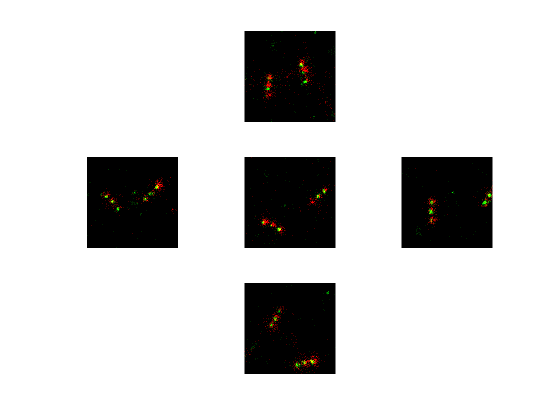

%We load the localizations
redLocalisations = commonFunctions.readCSVThunderSTORM('Data/ChromAbb_redPoints_light.csv');
greenLocalisations = commonFunctions.readCSVThunderSTORM('Data/ChromAbb_greenPoints_light.csv');

% We re-do the transform with re-scaled and rotated points
% To correct the localisations, we need to re-perform the transformation in
% the units of the localisations, rather than the units of the image.
% The image was created with 15 sub-pixels and 129 nm pixel size, meaning
% that we need to re-scale the transform as follows. Additionally, MATLAB
% images swap Y and X positions around, so for localizations, the columns
% of the red/green points are swapped
chromAbbTransformNm = fitgeotrans(redpts(:,[2,1])*(129/15),greenpts(:,[2,1])*(129/15),'affine');
[redLocalisationsCorrected(:,2),redLocalisationsCorrected(:,3)] = transformPointsForward(chromAbbTransformNm,redLocalisations(:,2),redLocalisations(:,3));

%And we visualise the corrected localizations with a histogram plot - also
%see Module 6
%The image needs to be flipped and rotated to match the imRGB from before
edges = linspace(0,max(greenLocalisations(:,3)),size(imRGB,1)+1);
binimGreen = fliplr(histcounts2(greenLocalisations(:,2),greenLocalisations(:,3),edges,edges))';
binimRed = fliplr(histcounts2(redLocalisationsCorrected(:,2),redLocalisationsCorrected(:,3),edges,edges))';
binimLocsRGB = zeros([size(binimGreen),3]);
binimLocsRGB(:,:,1) = binimRed./max(max(binimRed));
binimLocsRGB(:,:,2) = binimGreen./max(max(binimGreen));
binimLocsRGB= flipud(binimLocsRGB);

%Start figure - same subplots as performed previously
figure()
subplot(3,3,2)
imshow(binimLocsRGB(170:170+subplotsize,3970:3970+subplotsize,:)*5);
subplot(3,3,4)
imshow(binimLocsRGB(4040:4040+subplotsize,1300:1300+subplotsize,:)*5);
subplot(3,3,5)
imshow(binimLocsRGB(3750:3750+subplotsize,4140:4140+subplotsize,:)*5);
subplot(3,3,6)
imshow(binimLocsRGB(3450:3450+subplotsize,7390:7390+subplotsize,:)*5);
subplot(3,3,8)
imshow(binimLocsRGB(6680:6680+subplotsize,4150:4150+subplotsize,:)*5);